clc

num_boids = 5;
range_x = [-2.5, 2.5];
range_y = [-2.5, 2.5];
obstacles = [1.65,  1.60; 
             1.95, -1.55];
obstacle_radius = 0.5;
positions = [0.800 0.675; 
             0.575 0.175; 
             0.500 1.100; 
             0.125 0.625; 
             0.000 0.100];

boidAlt  = 0.51;

velocities = rand(num_boids, 2) - 0.5;

num_iterations    = 300;
cohesion_factor   = 0.02;
separation_factor = 0.05;
alignment_factor  = 0.01;
obstacle_avoidance_factor = 0.1;

trajectory01 = zeros(num_iterations,3);
trajectory02 = zeros(num_iterations,3);
trajectory03 = zeros(num_iterations,3);
trajectory04 = zeros(num_iterations,3);
trajectory05 = zeros(num_iterations,3);


% Conectar a CoppeliaSim
sim = remApi('remoteApi');

Note: always make sure you use the corresponding remoteApi library
(i.e. 32bit Matlab will not work with 64bit remoteApi, and vice-versa)


Conectado a CoppeliaSim


Handle del target obtenido correctamente


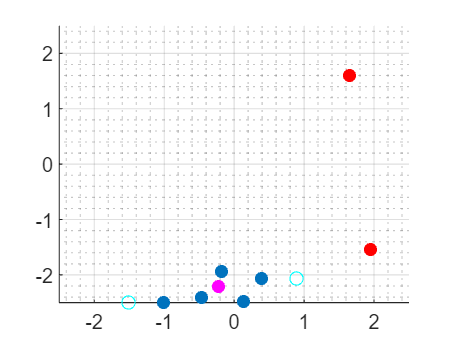

Simulación detenida y conexión cerrada


sim.simxFinish(-1);
clientID = sim.simxStart('127.0.0.1',19999,true,true,5000,5);

% Verificar la conexión
if (clientID > -1)
    disp('Conectado a CoppeliaSim');
    
    % Obtener el handle del target del cuadricóptero
    [res1, target_handle1] = sim.simxGetObjectHandle(clientID, 'Quadcopter_target',   sim.simx_opmode_blocking);
    [res2, target_handle2] = sim.simxGetObjectHandle(clientID, 'Quadcopter_target#0', sim.simx_opmode_blocking);
    [res3, target_handle3] = sim.simxGetObjectHandle(clientID, 'Quadcopter_target#1', sim.simx_opmode_blocking);
    [res4, target_handle4] = sim.simxGetObjectHandle(clientID, 'Quadcopter_target#2', sim.simx_opmode_blocking);
    [res5, target_handle5] = sim.simxGetObjectHandle(clientID, 'Quadcopter_target#3', sim.simx_opmode_blocking);
    [res6, target_handle6] = sim.simxGetObjectHandle(clientID, 'MassCenter',          sim.simx_opmode_blocking);

    if (res1 == sim.simx_return_ok && ...
        res2 == sim.simx_return_ok && ...
        res3 == sim.simx_return_ok && ...
        res4 == sim.simx_return_ok && ...
        res5 == sim.simx_return_ok && ...
        res6 == sim.simx_return_ok)
        disp('Handle del target obtenido correctamente');

       for t = 1:num_iterations
        
            %algoritmo Boid
            center_of_mass = mean(positions);

            trajectory01 (t,:) = [positions(1,:), boidAlt];
            trajectory02 (t,:) = [positions(2,:), boidAlt];
            trajectory03 (t,:) = [positions(3,:), boidAlt];
            trajectory04 (t,:) = [positions(4,:), boidAlt];
            trajectory05 (t,:) = [positions(5,:), boidAlt];

                % Calcular dirección de movimiento para cada boid
                for i = 1:num_boids
                    % Regla de cohesión
                    cohesion = (center_of_mass - positions(i,:)) * cohesion_factor;
                    
                    % Regla de separación
                    separation = zeros(1,2);
                    for j = 1:num_boids
                        if i ~= j
                            dist = norm(positions(i,:) - positions(j,:));
                            if dist < 0.1 % Evitar división por cero
                                separation = separation + rand(1,2); % Aplicar un pequeño alejamiento aleatorio
                            elseif dist < 0.5
                                separation = separation - (positions(j,:) - positions(i,:)) / dist^2;
                            end
                        end
                    end
                    separation = separation * separation_factor;
                    
                    % Regla de alineación
                    alignment = mean(velocities) * alignment_factor;
                    
                    % Evitar obstáculos
                    avoidance = zeros(1,2);
                    for k = 1:size(obstacles, 1)
                        dist_to_obstacle = norm(positions(i,:) - obstacles(k,:));
                        if dist_to_obstacle < obstacle_radius
                            avoidance = avoidance + (positions(i,:) - obstacles(k,:)) / dist_to_obstacle^2;
                        end
                    end
                    avoidance = avoidance * obstacle_avoidance_factor;
                    
                    % Actualizar velocidad
                    velocities(i,:) = velocities(i,:) + cohesion + separation + alignment + avoidance;
                    
                    % Limitar velocidad máxima
                    max_speed = 0.1;
                    speed = norm(velocities(i,:));
                    if speed > max_speed
                        velocities(i,:) = velocities(i,:) * max_speed / speed;
                    end
                    
                    % Actualizar posición
                    positions(i,:) = positions(i,:) + velocities(i,:);
                    
                    % Limitar posición dentro del rango
                    positions(i,1) = min(max(positions(i,1), range_x(1)), range_x(2));
                    positions(i,2) = min(max(positions(i,2), range_y(1)), range_y(2));
                end



                

            target_pos  = [positions(1,1), positions(1,2), boidAlt];
            target_pos1 = [positions(2,1), positions(2,2), boidAlt];
            target_pos2 = [positions(3,1), positions(3,2), boidAlt];
            target_pos3 = [positions(4,1), positions(4,2), boidAlt];
            target_pos4 = [positions(5,1), positions(5,2), boidAlt];
            target_pos5 = [center_of_mass(1), center_of_mass(2), boidAlt];

            [res1] = sim.simxSetObjectPosition(clientID, target_handle1, -1, target_pos, sim.simx_opmode_blocking);
            [res2] = sim.simxSetObjectPosition(clientID, target_handle2, -1, target_pos1, sim.simx_opmode_blocking);
            [res3] = sim.simxSetObjectPosition(clientID, target_handle3, -1, target_pos2, sim.simx_opmode_blocking);
            [res4] = sim.simxSetObjectPosition(clientID, target_handle4, -1, target_pos3, sim.simx_opmode_blocking);
            [res5] = sim.simxSetObjectPosition(clientID, target_handle5, -1, target_pos4, sim.simx_opmode_blocking);
            [res6] = sim.simxSetObjectPosition(clientID, target_handle6, -1, target_pos5, sim.simx_opmode_blocking);


            X_pos = sort(positions(:,1));
            Y_pos = sort(positions(:,2));
            R_pos  = X_pos(length(positions));
            L_pos  = X_pos(1);
            D_pos  = Y_pos(1);
            pos = find(positions(:,1)==R_pos);
            target_R = [positions(pos,1)+ 0.5, positions(pos,2)];
            pos = find(positions(:,1)==L_pos);
            target_L = [positions(pos,1)- 0.5, positions(pos,2)];
            pos = find(positions(:,2)==D_pos);
            target_D = [positions(pos,1), positions(pos,2)-0.5];
            Target = [target_R ; target_L; target_D];

 
            scatter(positions(:,1), positions(:,2), 'filled');
            hold on;
            scatter(obstacles(:,1), obstacles(:,2), 'r', 'filled');
            scatter(center_of_mass(1),center_of_mass(2),'magenta','filled')
            scatter(Target(:,1),Target(:,2),'cyan')
            grid on
            grid minor
            xlim(range_x);
            ylim(range_y);
            hold off;
            drawnow;

            
            if (res1 == sim.simx_return_ok && ...
                res2 == sim.simx_return_ok && ...
                res3 == sim.simx_return_ok && ...
                res4 == sim.simx_return_ok && ...
                res5 == sim.simx_return_ok && ...
                res6 == sim.simx_return_ok)
                
                %disp('Posición del target establecida correctamente');
                
                % Esperar un tiempo para que el cuadricóptero alcance el target
                pause(0.1);
                
                %disp('El cuadricóptero ha alcanzado el target');
            else
                disp('Error al establecer la posición del target');
            end
       end
        
    else
        disp('Error al obtener el handle del target');
    end
    
    % Detener la simulación y cerrar la conexión con coppelia
    sim.simxStopSimulation(clientID, sim.simx_opmode_blocking);
    sim.simxFinish(clientID);
    sim.delete();
    
    disp('Simulación detenida y conexión cerrada');
    
else
    disp('Error al conectar con CoppeliaSim');
end